# Racing Line Optimizer

### Import track data

track = readmatrix("Silverstone.csv")

track = 	1.0e+03 *

    0.0034   -0.0005    0.0066    0.0065
    0.0064    0.0036    0.0066    0.0065
    0.0093    0.0076    0.0066    0.0065
    0.0122    0.0117    0.0066    0.0065
    0.0152    0.0157    0.0066    0.0065
    0.0181    0.0198    0.0066    0.0065
    0.0210    0.0238    0.0066    0.0065
    0.0240    0.0279    0.0066    0.0065
    0.0269    0.0319    0.0066    0.0065
    0.0298    0.0360    0.0066    0.0065


### Define variables

trackName = 'Silverstone';
m = 750; % Mass of vehicle
ftmax = 16; % Max acceleration (m/s^2)
fbmax = 18; % Min acceleration (m/s^2)
fnmax = 30; % Max cornering acceleration (m/s^2)

### Generate optimized path

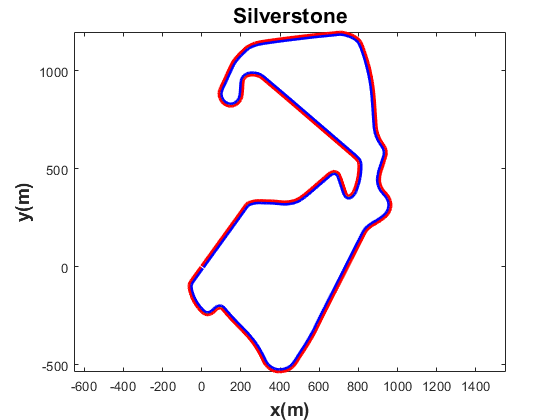

 Iter            Fval  Primal Infeas    Dual Infeas  Complementarity  
    0   -5.841348e+00   0.000000e+00   1.829838e+01     1.000000e+00  
    1   -1.900277e+01   5.551115e-16   9.149189e-03     2.502501e-01  
    2   -2.125436e+01   0.000000e+00   2.424521e-04     3.305909e-02  
    3   -2.430172e+01   0.000000e+00   2.157606e-06     3.923736e-03  
    4   -2.499782e+01   2.220446e-15   2.724901e-07     5.663693e-04  
    5   -2.505470e+01   7.771561e-16   1.112772e-07     4.061640e-04  
    6   -2.507673e+01   2.220446e-16   3.503843e-08     1.546732e-04  
    7   -2.508289e+01   1.110223e-16   5.894460e-09     2.625257e-05  
    8   -2.508351e+01   0.000000e+00   3.817604e-10     3.275064e-06  
    9   -2.508355e+01   0.000000e+00   2.665928e-10     2.281844e-06  
   10   -2.508360e+01   0.000000e+00   2.052651e-11     2.244297e-07  
   11   -2.508361e+01   0.000000e+00   9.960094e-12     9.716295e-08  
   12   -2.508361e+01   0.000000e+00   8.901959e-13     1.016847e-08  
   13 

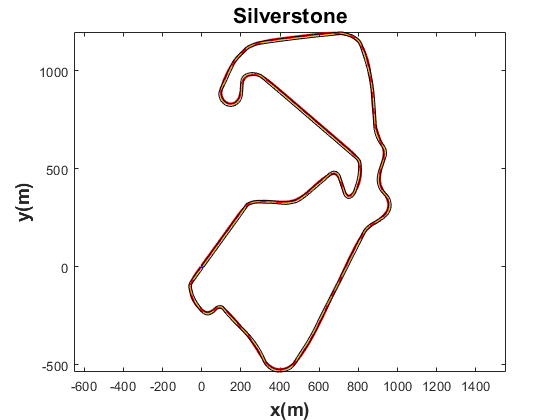

[trajMCP, trackData] = minCurvaturePathGenFunction(track,trackName);

% Click on the drop down menu to select the method for generating the optimized path

### Generate velocity profile

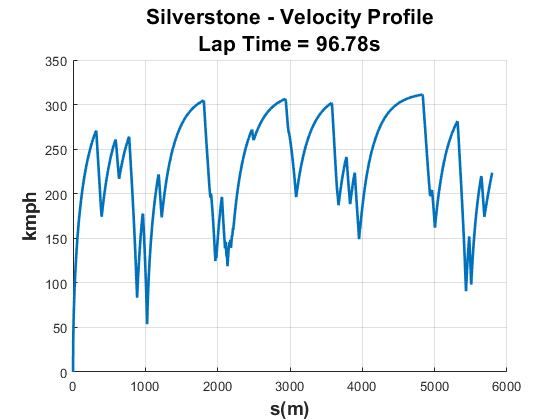

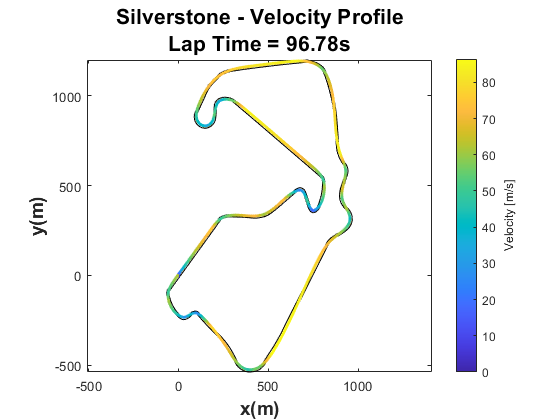

[velProf,len] = velProfCalcFunction(trajMCP,trackName,m,ftmax,fbmax,fnmax,trackData);

### References:

- The Silverstone racetrack data has been ta    ken from the following GitHub repository: [https://github.com/TUMFTM/racetrack-database](https://github.com/TUMFTM/racetrack-database) 

- The function, "velProfCalcFunction" uses the function, "curvature" that has been taken from the following File Exchange: [https://www.mathworks.com/matlabcentral/fileexchange/69452-curvature-of-a-1d-curve-in-a-2d-or-3d-space](https://www.mathworks.com/matlabcentral/fileexchange/69452-curvature-of-a-1d-curve-in-a-2d-or-3d-space) 